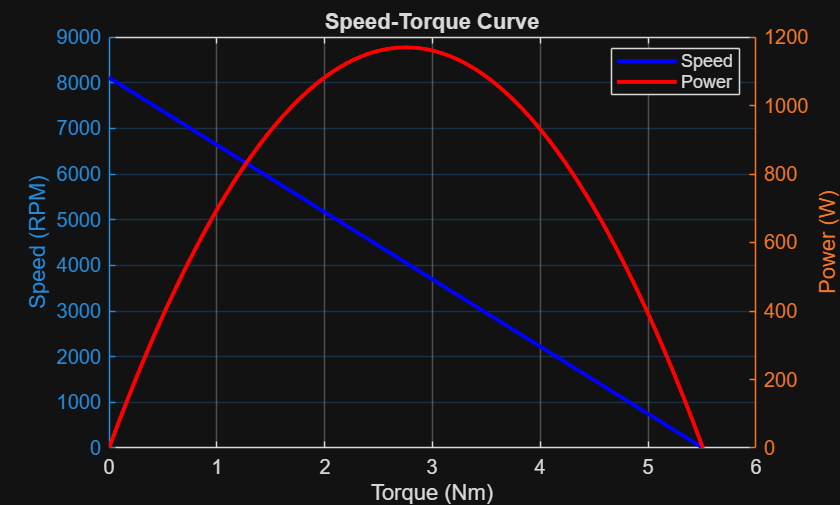

%oz.in = 0.0070615518333333 Nm
ozinToNm = 0.0070615518333333;
%Torque constant (Nm/A)
Kt = 7.99*ozinToNm;
%Speed Constant (RPM/V)
Kv = 169;
%SpeedTorque slope (RPM/Nm)
SpeedTorque = 10.4/ozinToNm;
%Nominal Supply Voltage (V)
VsNom = 48;
%No Load Speed (RPM)
w_noLoad = 8112;
%Peak Efficiency (%)
e_peak = 92/100;
cf = e_peak;
%Continuous stall torque no heat sink (Nm)
T_stallCont = 314*ozinToNm;
%Continuous Torque (Nm)
T_cont = 226*ozinToNm;
%Motor Constant (Nm/sqrt(W))
Km = 35*ozinToNm;
%Winding resistance (ohm)
R_winding = 0.053;
%Peak Output (W)
P_max = 967;
%I no load (A)
I_noLoad = 1.3;
%Damping Factor (Nm/KRPM)
b = 0.95*ozinToNm;
%Static Frict (Nm)
b_static = 2.7*ozinToNm;
%Winding Inductance (mH)
L_winding = 0.21;
%Rotor Inertia (Nm/s^2)
J_rotor = 565*10^(-4)*ozinToNm;
%Thermal Resistance winding to housing(degC/W)
R_thermal_windingToHousing = 0.44;
%Thermal Resistance housing to ambient (degC/W)
R_thermal_housingToAmbient = 1.12;
%Weight (Kg)
m_motor = 3.97;
%Max winding temp (degC)
T_max_winding = 180;


% Torque range
T = linspace(0, w_noLoad/SpeedTorque, 1000); % Generating 1000 torque points from 0 to stall torque

% Calculate speed for each torque point
w_fromSpeedTorque = w_noLoad - T.*SpeedTorque;
P_fromSpeedTorque = w_fromSpeedTorque*(2*pi()/(60)).*T;

% Plot speed-torque curve
figure;
yyaxis left;
plot(T , w_fromSpeedTorque, 'b', 'LineWidth', 2);
xlabel('Torque (Nm)');
ylabel('Speed (RPM)');
title('Speed-Torque Curve');
grid on;

yyaxis right;
plot(T, P_fromSpeedTorque, 'r', 'LineWidth', 2);
ylabel('Power (W)');
legend('Speed', 'Power', 'Location', 'best');
hold off

RPMMotMax = w_noLoad

RPMMotMax = 8112

% Get Motor RPM per specific Vehicle Speed
VehicleSpeed_KMPH = 15

VehicleSpeed_KMPH = 15

KMPHTomps = 1000/(60*60)

KMPHTomps = 0.2778

VehicleSpeed = VehicleSpeed_KMPH*KMPHTomps

VehicleSpeed = 4.1667

TireCircum = 1.75

TireCircum = 1.7500

GearRatio = 12/1

GearRatio = 12

RPM_tire = VehicleSpeed/TireCircum*60

RPM_tire = 142.8571

RPM_motor = RPM_tire*GearRatio

RPM_motor = 1.7143e+03

% Calculate the force given a current in the motor
MotorCurrent = 10;
Tmotor = MotorCurrent*Kt % Kt = Nm/A, so this is when motor draws 10A?

Tmotor = 0.5642

Tgearbox = Tmotor*GearRatio % Is this gear ratio? Replaced with gear ratio but used to be 25

Tgearbox = 6.7706

F = Tgearbox/0.203

F = 33.3528

p = F*VehicleSpeed

p = 138.9699

% Force required to move the car forwards?

m = 150; % Is the car 150kg?
a = 0.36; % Where is this acceleration from?
F = m*a % output force

F = 54

% Just get the Vehicle Speed per a specific Motor RPM

MotRPM = 7000;
WheelRPM = MotRPM/GearRatio

WheelRPM = 583.3333

VehicleSpeed = WheelRPM*TireCircum/60

VehicleSpeed = 17.0139

VehicleSpeed_KMPH = VehicleSpeed/1000*(60*60)

VehicleSpeed_KMPH = 61.2500

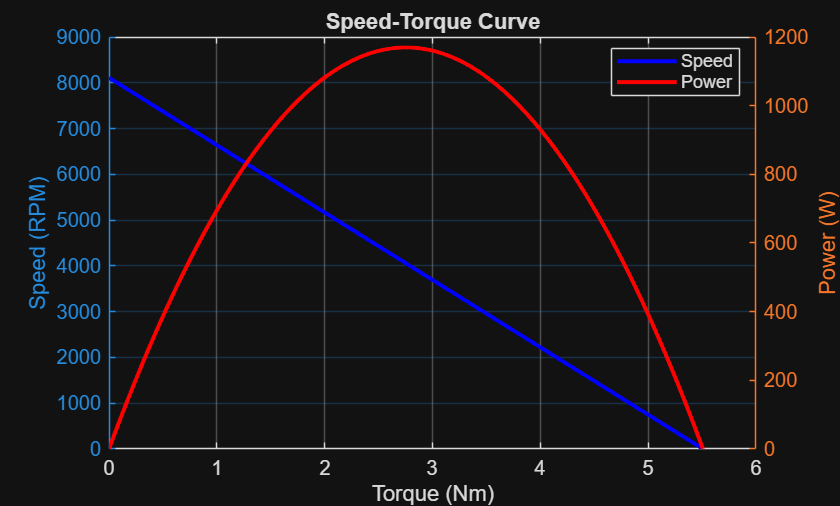


hold off

figure
GRs = [25 20 16 15 12 9]

GRs =     25    20    16    15    12     9


WheelSpeedDistribution = (RPMMotMax*cf)./GRs

WheelSpeedDistribution =   298.5216  373.1520  466.4400  497.5360  621.9200  829.2267


VehicleSpeedDistribution = WheelSpeedDistribution*TireCircum/60 % meters per second

VehicleSpeedDistribution =     8.7069   10.8836   13.6045   14.5115   18.1393   24.1858


VehicleSpeedDistribution_KMPH = VehicleSpeedDistribution*60*60/1000

VehicleSpeedDistribution_KMPH =    31.3448   39.1810   48.9762   52.2413   65.3016   87.0688


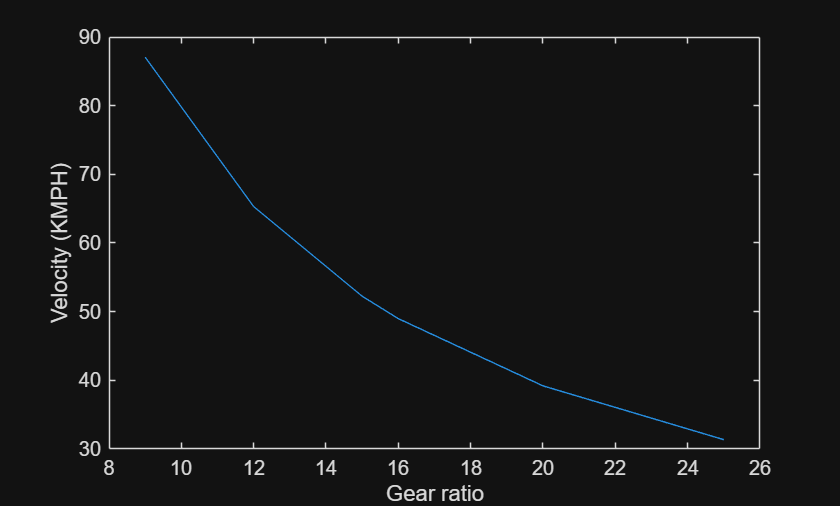


plot(GRs,VehicleSpeedDistribution_KMPH)
xlabel("Gear ratio")
ylabel("Velocity (KMPH)")


treq = 35/60;
dist = 15.33;
vreq = dist/treq

vreq = 26.2800